clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("方涵复测_2025_09_12.xlsx");

shendu = 0.015;
phi = deg2rad(65);
shenglunum = 4;
a = shendu*ones(1,2*shenglunum);
distanceThreshold = 0.2;



PAB = [0.655; -0.943; -0.478 ];
P_bound1 = num([72,74,73],2);
P_bound2 = num([72,74,73],3);

xl = num(27,~isnan(num(27,:)));
yl = num(29,~isnan(num(29,:)));
zl = num(28,~isnan(num(28,:)));
side_faces_transformed1 =[xl;yl;zl];

xt = num(32,~isnan(num(32,:)));
yt = num(34,~isnan(num(34,:)));
zt = num(33,~isnan(num(33,:)));
side_faces_transformed3 =[xt;yt;zt];

xr = num(37,~isnan(num(37,:)));
yr = num(39,~isnan(num(39,:)));
zr = num(38,~isnan(num(38,:)));
side_faces_transformed5 =[xr;yr;zr];


xb = num(42,~isnan(num(42,:)));
yb = num(44,~isnan(num(44,:)));
zb = num(43,~isnan(num(43,:)));
side_faces_transformed7 =[xb;yb;zb];


xlb = num(47,~isnan(num(47,:)));
ylb = num(49,~isnan(num(49,:)));
zlb = num(48,~isnan(num(48,:)));
side_faces_transformed8 =[xlb;ylb;zlb];


xlt = num(52,~isnan(num(52,:)));
ylt = num(54,~isnan(num(54,:)));
zlt = num(53,~isnan(num(53,:)));
side_faces_transformed2 =[xlt;ylt;zlt];


xrt = num(57,~isnan(num(57,:)));
yrt = num(59,~isnan(num(59,:)));
zrt = num(58,~isnan(num(58,:)));
side_faces_transformed4 =[xrt;yrt;zrt];

xrb = num(62,~isnan(num(62,:)));
yrb = num(64,~isnan(num(64,:)));
zrb = num(63,~isnan(num(63,:)));
side_faces_transformed6 =[xrb;yrb;zrb];


% side_faces_transformed2 = [];
% side_faces_transformed4 = [];

[PlaneParaOut8,TrianglePoints8,MaxDis,tt1,tt2,tt3,tt4,tt5,tt6,tt7,tt8,LenDaoJiao] = planefit8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,distanceThreshold);

Isempty FACE2468: 0.000000, 0.000000, 15.000000, 0.000000




Ti = ShengDaoGaoDu(shenglunum);
[PointTable_A_off8,PointTable_B_off8,XieMianPianYi,BianHao] = Calculate_rectangle_from_vertex8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold);

Isempty FACE2468: 0.000000, 0.000000, 15.000000, 0.000000


figure
hold on 
box on
grid on
axis equal
% scatter3(side_faces_transformed1(1,:),side_faces_transformed1(2,:),side_faces_transformed1(3,:),15,'yellow')
% scatter3(side_faces_transformed2(1,:),side_faces_transformed2(2,:),side_faces_transformed2(3,:),15,'green')
% scatter3(side_faces_transformed3(1,:),side_faces_transformed3(2,:),side_faces_transformed3(3,:),15,'red')
% scatter3(side_faces_transformed4(1,:),side_faces_transformed4(2,:),side_faces_transformed4(3,:),15,'blue')
% scatter3(side_faces_transformed5(1,:),side_faces_transformed5(2,:),side_faces_transformed5(3,:),15,'blue')
% scatter3(side_faces_transformed6(1,:),side_faces_transformed6(2,:),side_faces_transformed6(3,:),15,'blue')
scatter3(side_faces_transformed7(1,:),side_faces_transformed7(2,:),side_faces_transformed7(3,:),15,'blue')
scatter3(side_faces_transformed8(1,:),side_faces_transformed8(2,:),side_faces_transformed8(3,:),15,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end


% scatter3(ZhouDian(1,:),ZhouDian(2,:),ZhouDian(3,:),50,'filled','black')
% scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
% scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

% AB面点
scatter3(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),50,'filled','r')
text(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),['A',num2str(BianHao(1,1))])


scatter3(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),50,'filled','g')
text(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),['A',num2str(BianHao(1,2))])

scatter3(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),50,'filled','b')
text(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),['A',num2str(BianHao(1,3))])

scatter3(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),50,'filled','c')
text(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),['A',num2str(BianHao(1,4))])

scatter3(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),50,'filled','m')
text(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),['A',num2str(BianHao(1,5))])

scatter3(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),50,'filled','y')
text(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),['A',num2str(BianHao(1,6))])

scatter3(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),50,'filled','y')
text(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),['A',num2str(BianHao(1,7))])

scatter3(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),50,'filled','k')
text(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),['A',num2str(BianHao(1,8))])


norm(PointTable_A_off8(:,6)-PointTable_B_off8(:,6))

ans = 1.2271

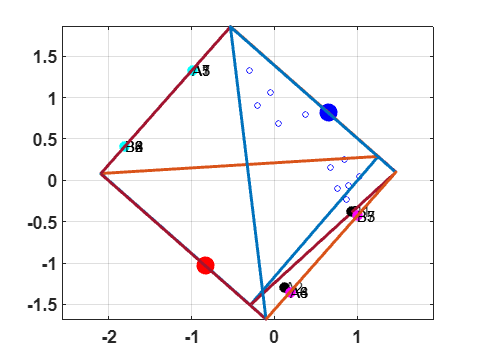


scatter3(P_bound1(1),P_bound1(2),P_bound1(3),150,'r','filled')
scatter3(P_bound2(1),P_bound2(2),P_bound2(3),150,'b','filled')


scatter3(PointTable_B_off8(1,1),PointTable_B_off8(2,1),PointTable_B_off8(3,1),50,'filled','r')
text(PointTable_B_off8(1,1),PointTable_B_off8(2,1),PointTable_B_off8(3,1),['B',num2str(BianHao(2,1))])


scatter3(PointTable_B_off8(1,2),PointTable_B_off8(2,2),PointTable_B_off8(3,2),50,'filled','g')
text(PointTable_B_off8(1,2),PointTable_B_off8(2,2),PointTable_B_off8(3,2),['B',num2str(BianHao(2,2))])

scatter3(PointTable_B_off8(1,3),PointTable_B_off8(2,3),PointTable_B_off8(3,3),50,'filled','b')
text(PointTable_B_off8(1,3),PointTable_B_off8(2,3),PointTable_B_off8(3,3),['B',num2str(BianHao(2,3))])

scatter3(PointTable_B_off8(1,4),PointTable_B_off8(2,4),PointTable_B_off8(3,4),50,'filled','c')
text(PointTable_B_off8(1,4),PointTable_B_off8(2,4),PointTable_B_off8(3,4),['B',num2str(BianHao(2,4))])

scatter3(PointTable_B_off8(1,5),PointTable_B_off8(2,5),PointTable_B_off8(3,5),50,'filled','m')
text(PointTable_B_off8(1,5),PointTable_B_off8(2,5),PointTable_B_off8(3,5),['B',num2str(BianHao(2,5))])

scatter3(PointTable_B_off8(1,6),PointTable_B_off8(2,6),PointTable_B_off8(3,6),50,'filled','y')
text(PointTable_B_off8(1,6),PointTable_B_off8(2,6),PointTable_B_off8(3,6),['B',num2str(BianHao(2,6))])

scatter3(PointTable_B_off8(1,7),PointTable_B_off8(2,7),PointTable_B_off8(3,7),50,'filled','y')
text(PointTable_B_off8(1,7),PointTable_B_off8(2,7),PointTable_B_off8(3,7),['B',num2str(BianHao(2,7))])

scatter3(PointTable_B_off8(1,8),PointTable_B_off8(2,8),PointTable_B_off8(3,8),50,'filled','k')
text(PointTable_B_off8(1,8),PointTable_B_off8(2,8),PointTable_B_off8(3,8),['B',num2str(BianHao(2,8))])



% PP16 = TrianglePoints8(:,[7,8,14,20,26,32,38,44,3,9,18,24,30,36,42,48]);
% scatter3(PP16(1,2),PP16(2,2),PP16(3,2),50,'filled','red');
% scatter3(PP16(1,3),PP16(2,3),PP16(3,3),50,'filled','green');


% scatter3(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1),50,'filled','r')
% text(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1),'P1')
% 
% scatter3(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2),50,'filled','g')
% text(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2),'P2')
% 
% scatter3(PPP4OUT(1,3),PPP4OUT(2,3),PPP4OUT(3,3),50,'filled','b')
% text(PPP4OUT(1,3),PPP4OUT(2,3),PPP4OUT(3,3),'P3')
% 
% scatter3(PPP4OUT(1,4),PPP4OUT(2,4),PPP4OUT(3,4),50,'filled','c')
% text(PPP4OUT(1,4),PPP4OUT(2,4),PPP4OUT(3,4),'P4')
% 
% scatter3(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5),50,'filled','c')
% text(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5),'P5')
% 
% scatter3(PPP4OUT(1,6),PPP4OUT(2,6),PPP4OUT(3,6),50,'filled','c')
% text(PPP4OUT(1,6),PPP4OUT(2,6),PPP4OUT(3,6),'P6')
% 
% scatter3(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7),50,'filled','c')
% text(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7),'P7')
% 
% scatter3(PPP4OUT(1,8),PPP4OUT(2,8),PPP4OUT(3,8),50,'filled','c')
% text(PPP4OUT(1,8),PPP4OUT(2,8),PPP4OUT(3,8),'P8')



% scatter3(PP(1,1),PP(2,1),PP(3,1),50,'filled','r')
% text(PP(1,1),PP(2,1),PP(3,1),'T1')
% 
% scatter3(PP(1,2),PP(2,2),PP(3,2),50,'filled','g')
% text(PP(1,2),PP(2,2),PP(3,2),'T2')
% 
% scatter3(PP(1,3),PP(2,3),PP(3,3),50,'filled','b')
% text(PP(1,3),PP(2,3),PP(3,3),'T3')
% 
% scatter3(PP(1,4),PP(2,4),PP(3,4),50,'filled','c')
% text(PP(1,4),PP(2,4),PP(3,4),'T4')
% 
% scatter3(PP(1,5),PP(2,5),PP(3,5),50,'filled','c')
% text(PP(1,5),PP(2,5),PP(3,5),'T5')
% 
% scatter3(PP(1,6),PP(2,6),PP(3,6),50,'filled','c')
% text(PP(1,6),PP(2,6),PP(3,6),'T6')
% 
% scatter3(PP(1,7),PP(2,7),PP(3,7),50,'filled','c')
% text(PP(1,7),PP(2,7),PP(3,7),'T7')
% 
% scatter3(PP(1,8),PP(2,8),PP(3,8),50,'filled','c')
% text(PP(1,8),PP(2,8),PP(3,8),'T8')

## 点测试

[PlaneParaOut4,TrianglePoints4,~,~] = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints4)

Pin =    -1.0978
   -0.7973
    0.2955


Pout =     0.4703
    0.9792
    0.2955


UPP =    -1.0978
   -0.7973
    1.5857


b = 2.6616

h = 2.5804

w = 2.3695

Tao =     0.6618
    0.7497
         0


PP =    -2.0955    0.0834    1.5857
   -2.0955    0.0834   -0.9947
   -0.5274    1.8599    1.5857
   -0.5274    1.8599   -0.9947
   -0.1001   -1.6779    1.5857
    1.4680    0.0985    1.5857
   -0.1001   -1.6779   -0.9947
    1.4680    0.0985   -0.9947


% PP =PP';
% scatter3(PP(1,1),PP(2,1),PP(3,1),50,'r','filled')
% scatter3(PP(1,2),PP(2,2),PP(3,2),50,'g','filled')
% scatter3(PP(1,3),PP(2,3),PP(3,3),50,'b','filled')
% scatter3(PP(1,4),PP(2,4),PP(3,4),50,'c','filled')
% scatter3(PP(1,5),PP(2,5),PP(3,5),50,'m','filled')
% scatter3(PP(1,6),PP(2,6),PP(3,6),50,'y','filled')
% scatter3(PP(1,7),PP(2,7),PP(3,7),50,'k','filled')
% scatter3(PP(1,8),PP(2,8),PP(3,8),50,'r','filled')
% 
% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')
% toff = [-a(1:shenglunum)./tan(phi),a(1:shenglunum)./tan(phi)];
% [PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)
% 
% 
% scatter3(PointTable_B_off(1,1),PointTable_B_off(2,1),PointTable_B_off(3,1),150,'filled','r')
% scatter3(PointTable_B_off(1,2),PointTable_B_off(2,2),PointTable_B_off(3,2),150,'filled','g')
% scatter3(PointTable_B_off(1,3),PointTable_B_off(2,3),PointTable_B_off(3,3),150,'filled','b')
% scatter3(PointTable_B_off(1,4),PointTable_B_off(2,4),PointTable_B_off(3,4),150,'filled','c')
% scatter3(PointTable_B_off(1,5),PointTable_B_off(2,5),PointTable_B_off(3,5),150,'filled','m')
% scatter3(PointTable_B_off(1,6),PointTable_B_off(2,6),PointTable_B_off(3,6),150,'filled','y')
% 
% 
% scatter3(PointTable_B_off(1,8),PointTable_B_off(2,8),PointTable_B_off(3,8),150,'filled','k')
% scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','black')

LenDaoJiao(5)

ans = 0.2161

LenDaoJiao(6)

ans = 0.2566

rad2deg(atan(LenDaoJiao(5)./LenDaoJiao(6)))

ans = 40.0967

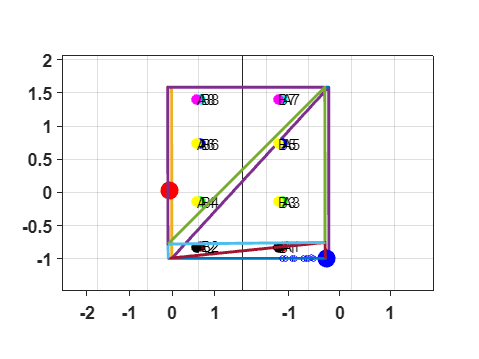

view(90-rad2deg(atan(LenDaoJiao(5)./LenDaoJiao(6))),0)


% 
% [PlaneParaOut,TrianglePoints,MaxDis,distancesFianal2]  = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
% aa = PlaneParaOut(1:3,3);
% bb = PlaneParaOut(1:3,4);
% rad2deg(acos(dot(aa,bb)./norm(aa)./norm(bb)))
% 
% PPP4OUT = TrianglePoints4(:,[1,2,3,6,9,12,15,18]);
% scatter3(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1),50,'filled','r')
% text(PPP4OUT(1,1),PPP4OUT(2,1),PPP4OUT(3,1)+0.2,['PPP4OUT',num2str(1)])
% scatter3(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2),50,'filled','r')
% text(PPP4OUT(1,2),PPP4OUT(2,2),PPP4OUT(3,2)+0.2,['PPP4OUT',num2str(2)])
% scatter3(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5),50,'filled','r')
% text(PPP4OUT(1,5),PPP4OUT(2,5),PPP4OUT(3,5)+0.2,['PPP4OUT',num2str(5)])
% scatter3(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7),50,'filled','r')
% text(PPP4OUT(1,7),PPP4OUT(2,7),PPP4OUT(3,7)+0.2,['PPP4OUT',num2str(7)])
% 
% 
% PPP8OUT = TrianglePoints8(:,[1;8;14;20;26;32;38;2;3;9;18;24;30;36;42;6]);
% scatter3(PPP8OUT(1,1),PPP8OUT(2,1),PPP8OUT(3,1),50,'filled','b')
% text(PPP8OUT(1,1),PPP8OUT(2,1),PPP8OUT(3,1),['PPP8OUT',num2str(1)])
% scatter3(PPP8OUT(1,2),PPP8OUT(2,2),PPP8OUT(3,2),50,'filled','b')
% text(PPP8OUT(1,2),PPP8OUT(2,2),PPP8OUT(3,2),['PPP8OUT',num2str(2)])
% scatter3(PPP8OUT(1,3),PPP8OUT(2,3),PPP8OUT(3,3),50,'filled','b')
% text(PPP8OUT(1,3),PPP8OUT(2,3),PPP8OUT(3,3),['PPP8OUT',num2str(3)])
% scatter3(PPP8OUT(1,4),PPP8OUT(2,4),PPP8OUT(3,4),50,'filled','b')
% text(PPP8OUT(1,4),PPP8OUT(2,4),PPP8OUT(3,4),['PPP8OUT',num2str(4)])
% 
% scatter3(PPP8OUT(1,5),PPP8OUT(2,5),PPP8OUT(3,5),50,'filled','b')
% text(PPP8OUT(1,5),PPP8OUT(2,5),PPP8OUT(3,5),['PPP8OUT',num2str(5)])
% scatter3(PPP8OUT(1,6),PPP8OUT(2,6),PPP8OUT(3,6),50,'filled','b')
% text(PPP8OUT(1,6),PPP8OUT(2,6),PPP8OUT(3,6),['PPP8OUT',num2str(6)])
% scatter3(PPP8OUT(1,7),PPP8OUT(2,7),PPP8OUT(3,7),50,'filled','b')
% text(PPP8OUT(1,7),PPP8OUT(2,7),PPP8OUT(3,7),['PPP8OUT',num2str(7)])
% scatter3(PPP8OUT(1,8),PPP8OUT(2,8),PPP8OUT(3,8),50,'filled','b')
% text(PPP8OUT(1,8),PPP8OUT(2,8),PPP8OUT(3,8),['PPP8OUT',num2str(8)])



## 偏移测试

if shendu==0
    ZeroPY = PointTable_B_off8(:,8);
    save('0py.mat','ZeroPY');
end


load('0py.mat');
YPY = PointTable_B_off8(:,8);

DISR = norm(ZeroPY-YPY)

DISR = 0.3487

DISLL = sqrt( (shendu./tan(phi))^2+XieMianPianYi(8).^2)

DISLL = 0.0191